path = fullfile("FaceDatabase","lfw-funneled-scaled-224");
imds = imageDatastore(path, "IncludeSubfolders",true,"LabelSource","foldernames");

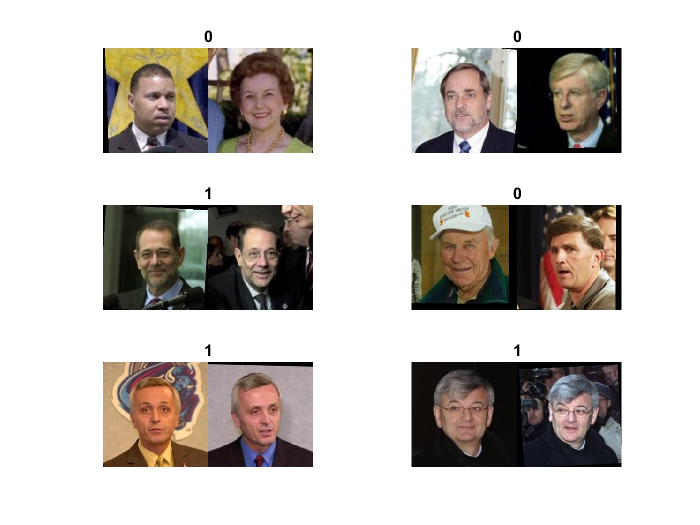

batchSize = 10;
iter = 1;

[simTB, disTB] = readLFWPairsDevTxt("Common/lfw-details/pairsDevTrain.txt");
[a, b, l] = LFWRandomPairBatchLoader(imds, simTB, disTB, 6, 0.5);
figure
for i = 1:6
    subplot(3,2,i);
    imshowpair(a(:,:,:,i)/255,b(:,:,:,i)/255,"montage");
    title(l(i));
end

function [batch1 batch2 labels] = LFWPairBatchLoader(imds, similarTable, dissimilarTable, batchSize, similarWeight)

    % rectify and calculate batch size
    
    if mod(batchSize, 2) == 1
        batchSize = batchSize + 1;
    end
        
    simBatchSize = round(batchSize * similarWeight);
    disBatchSize = batchSize - simBatchSize;
    
    % randomly select pairs
    
    simLen = size(similarTable, 1);
    disLen = size(dissimilarTable, 1);
    
    simChoices = randperm(simLen, simBatchSize);
    disChoices = randperm(disLen, disBatchSize);
        
    % filter selection and shuffle
    
    similarTable.isSimilar = ones(size(similarTable,1),"double");
    dissimilarTable.isSimilar = zeros(size(dissimilarTable,1),"double");
    
    wholeTable = [similarTable(simChoices,:) ; dissimilarTable(disChoices,:)];
    wholeTable = wholeTable(randperm(size(wholeTable,1)), :); % shuffle rows by indexing randomly
    
    % split pair into A and B and return their label
    
    setATable = wholeTable(:,1:2);
    setBTable = wholeTable(:,3:4);
    
    labels = wholeTable.isSimilar;
    
    % find global index of A subjects and B subjects
    
    %   get the name of the files
    parts = split(imds.Files, filesep); % whole path
    parts = split(parts(:, end), ".");  % 'NAME_0001.jpg'
    parts = parts(:,1);                 % 'NAME_0001'
    
    %   'NAME' + '_' + '0001'
    setATable.nameA = strcat(setATable.nameA, "_", arrayfun(@(x) sprintf('%04d',x),setATable.a,'un',0));
    setBTable.nameB = strcat(setBTable.nameB, "_", arrayfun(@(x) sprintf('%04d',x),setBTable.b,'un',0));
    
    % path of A subjects = imds.Files(setAIdx)
    % path of B subjects = imds.FIles(setBIdx)
    % match the names from A to filenames and B to filenames
%     [~, ~, setAIdx] = intersect(setATable.nameA, parts, 'stable');
%     [~, ~, setBIdx] = intersect(setBTable.nameB, parts, 'stable');
    setAIdx = findAll(parts, setATable.nameA);
    setBIdx = findAll(parts, setBTable.nameB);    
    
    % load all images in    
    imSize = size(readimage(imds,1));
    batch1 = zeros([imSize batchSize], "single");
    batch2 = zeros([imSize batchSize], "single");
    for i = 1:batchSize
        batch1(:,:,:,i) = readimage(imds,setAIdx(i));
        batch2(:,:,:,i) = readimage(imds,setBIdx(i));
    end
    
end

function out = findAll(A, B)

    out = zeros(size(B,1),1);
    for i = 1:size(B,1)
        out(i) = find(A == B(i), 1);
    end

end